# Experimental Methods HW #7 Dan Lawson

## Problem 1: Convergence

% Load the file 'SAMPLE.MAT' from Canvas, sampled at 5 kHz 100,001 points

% a) Compute the Mean and STD of the signal

U = x; % Reinitialize given velocity signal (m/s)

U_mean = mean(U) % mean (m/s)

U_mean = 2.1606

U_std = std(U) % STD (m/s)

U_std = 0.1870

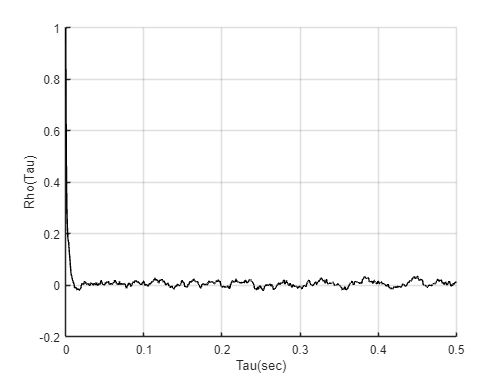


% b) Perform the convergence studies to determine minimum signal duration
% needed to correctly measure the mean value

P_fsamp = 5000;
[rho,lags] = xcorr(U - mean(U),'coeff');

figure
hold on

plot(lags/P_fsamp, rho, '-k');
grid on
xlim([0 0.5])
ylabel('Rho(Tau)')
xlabel('Tau(sec)')

hold off


tcorr = 0.02

tcorr = 0.0200

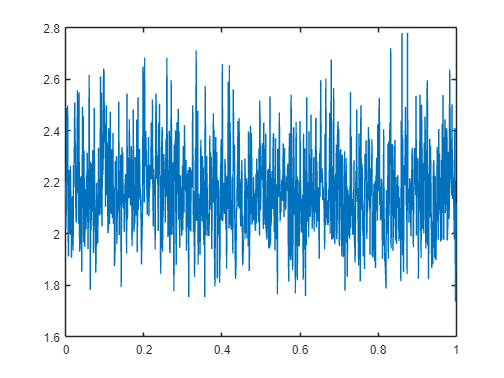


D_samp = 1 / tcorr; % Downsample frequency from Tcorr value

samp_ratio = round(P_fsamp / D_samp); % Ratio of sampling rates

P_down = downsample(U, samp_ratio); % downsampled Pressure Ratio

T_down = linspace(0, 1,length(P_down));

plot(T_down, P_down)

corr_std = std(P_down) % 

corr_std = 0.1798

corr_error = t_value(0.9, 1000) * (corr_std / sqrt(1001)); % Nu = N - 1, where N is our sample count
U_down_mean = mean(U) %

U_down_mean = 2.1606





% c)



% d)  



## Problem 2: Thermocouple

t = [1.5 3 4.5 6 7.5 9];
T = [24.5 26.9 28.3 29.2 29.7 29.9];


## Problem 3: Mass Flow Rate

V = [1.76 1.80 1.72 1.78 1.75]; % Differential pressure outputs (V)
V_mean = mean(V)
P_difs = ((V - 1) * 0.2) * 6895 % Pa
























